A = imread('Elevation.tif');
[X, cmap] = imread('Elevation.tif');
%%A(isnan(A))=0;
size(A)

ans =         1529        1667


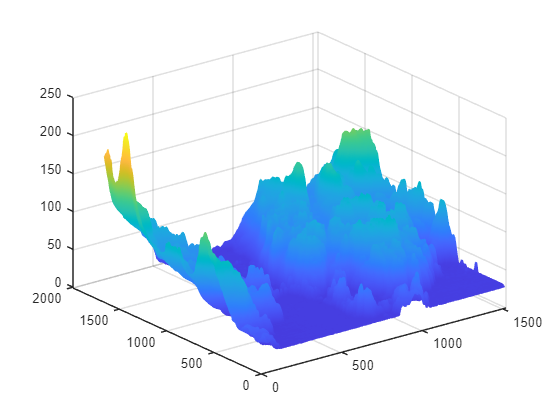


[X, Y] = meshgrid(1:size(A,2), 1:size(A,1)); % Create all (x,y) points to plot

mesh(Y,X,A)

A = imread('2m.tif');
[X, cmap] = imread('2m.tif');
%%A(isnan(A))=0;
size(A)

ans =         3329        3742           4


F = (A(:,:,1:3));
size(F)

ans =         3329        3742           3


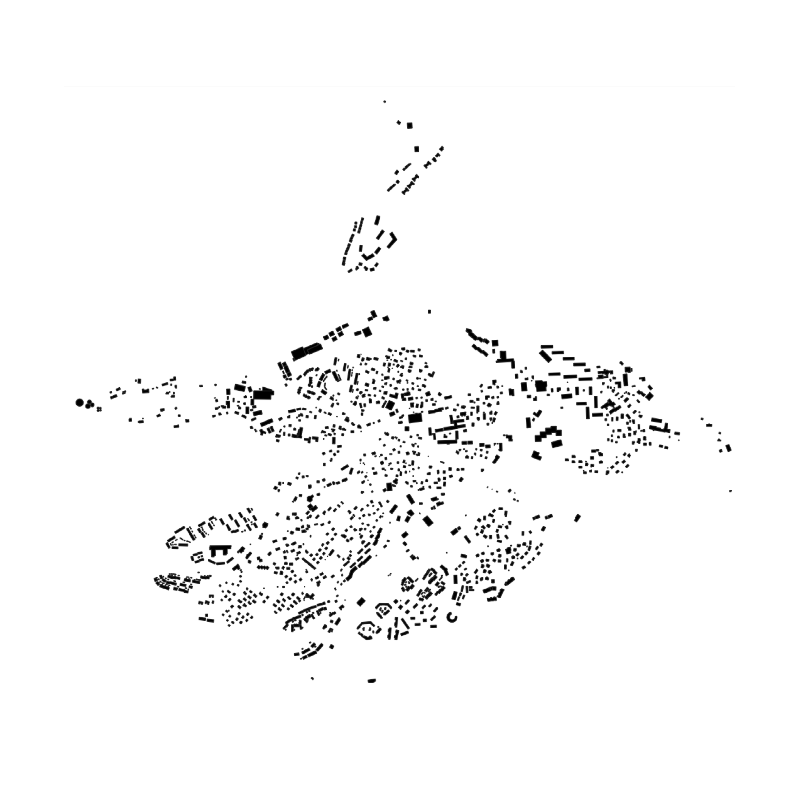

imshow(F)

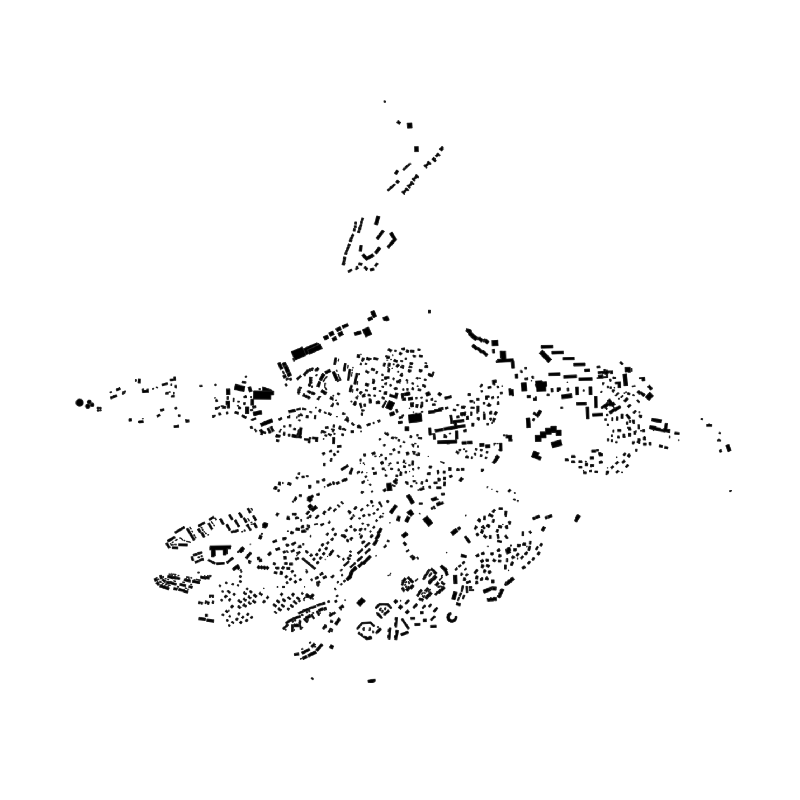


Igr = rgb2gray(F);
imshow(Igr, []);

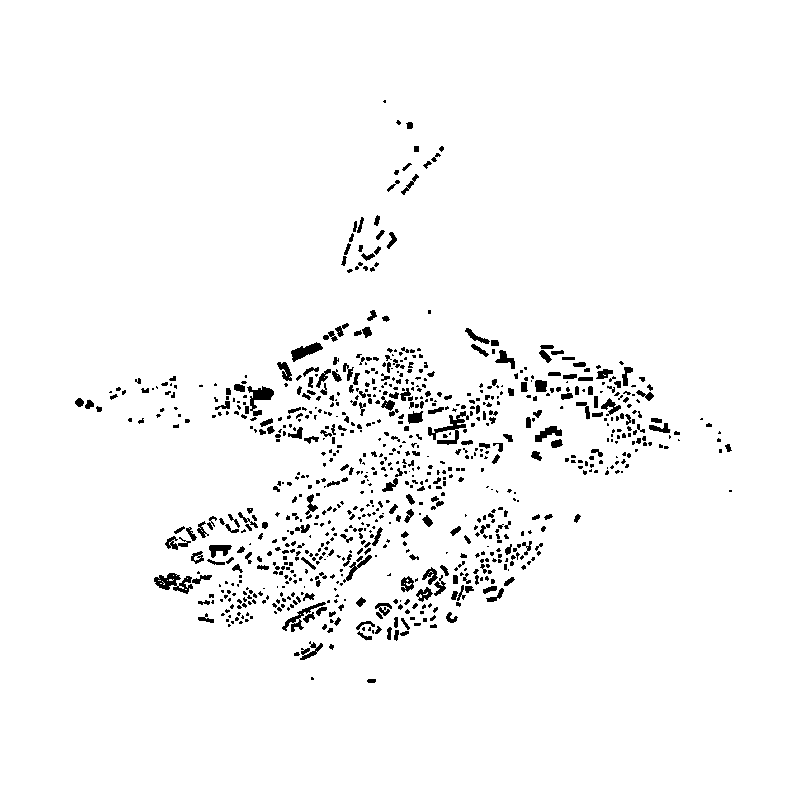

[X, map] = gray2ind(Igr, 64);
indices = find(abs(X)>49);
X(indices) = 255;

indices2 = find(abs(X)<49);
X(indices2) = 0;

imshow(X, map);

size(X)

ans =         3329        3742


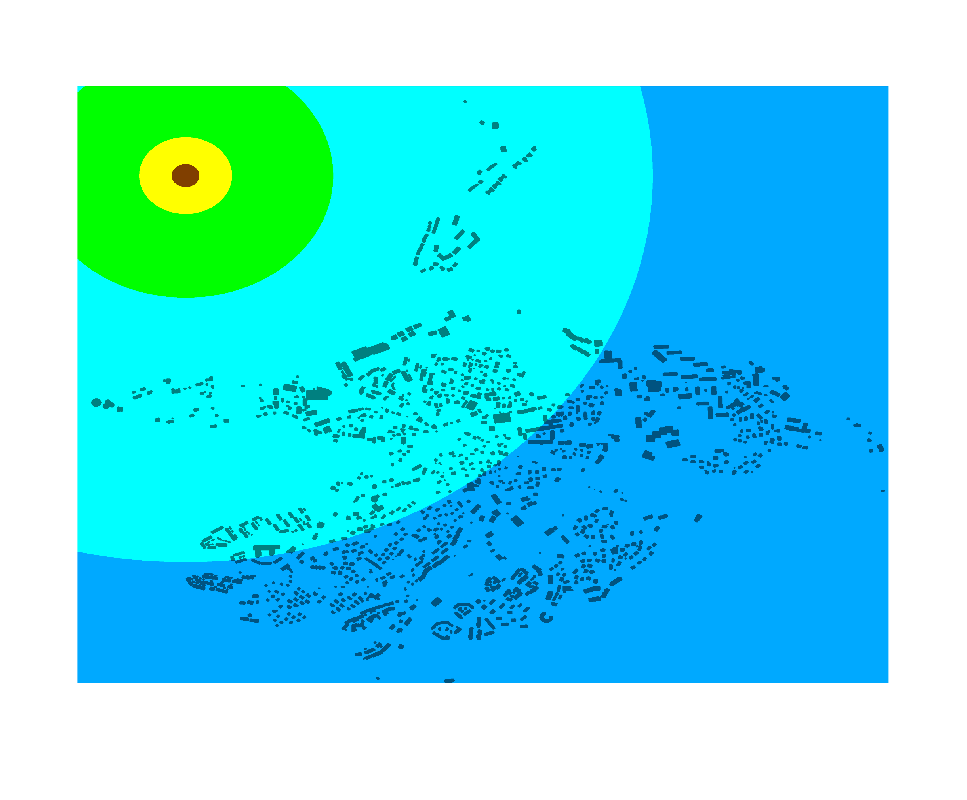


Transmitterx = 500;
Transmittery = 500;
TransmitterHeight = 25;
ReceiverHeight = 1.5;
Wavelength = 3.0*10^8/3.5*10^9;
for y = 1:3742
    for x = 1:3329
        D = sqrt((Transmitterx - x)^2+(Transmittery-y)^2+(TransmitterHeight - ReceiverHeight)^2);
        path2 = 20*log10(4*pi*D/0.0856549);
        
        if path2 < 70
            if X(x,y) == 255
            F(x,y,1) = 128;
            F(x,y,2) = 0;
            F(x,y,3) = 0;
            else
            F(x,y,1) = 255;
            F(x,y,2) = 0;
            F(x,y,3) = 0;

            end
        elseif path2 < 80
            if X(x,y) == 255
            F(x,y,1) = 128;
            F(x,y,2) = 63;
            F(x,y,3) = 0;
            else
            F(x,y,1) = 254;
            F(x,y,2) = 169;
            F(x,y,3) = 0;

            end

        elseif path2 < 90
            if X(x,y) == 0
            F(x,y,1) = 128;
            F(x,y,2) = 128;
            F(x,y,3) = 0;
            else
            F(x,y,1) = 255;
            F(x,y,2) = 255;
            F(x,y,3) = 0;

            end

        elseif path2 < 100
            if X(x,y) == 0
                F(x,y,1) = 0;
                F(x,y,2) = 128;
                F(x,y,3) = 0;
            else
                F(x,y,1) = 0;
                F(x,y,2) = 255;
                F(x,y,3) = 0;

            end
         
        elseif path2 < 110
            if X(x,y) == 0
            F(x,y,1) = 0;
            F(x,y,2) = 128;
            F(x,y,3) = 128;
            else
            F(x,y,1) = 0;
            F(x,y,2) = 255;
            F(x,y,3) = 255;

            end

        elseif path2 < 120
            if X(x,y) == 0
            F(x,y,1) = 0;
            F(x,y,2) = 83;
            F(x,y,3) = 128;
            else
            F(x,y,1) = 0;
            F(x,y,2) = 169;
            F(x,y,3) = 255;

            end

        elseif path2 > 120
            if X(x,y) == 0
            F(x,y,1) = 0;
            F(x,y,2) = 63;
            F(x,y,3) = 128;
            else
            F(x,y,1) = 0;
            F(x,y,2) = 0;
            F(x,y,3) = 255;

            end
        end
        
    
    end
end

imshow(F)